# Estimation, Filtering and Detection

## Homework 2C: Asynchronous Sampling

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

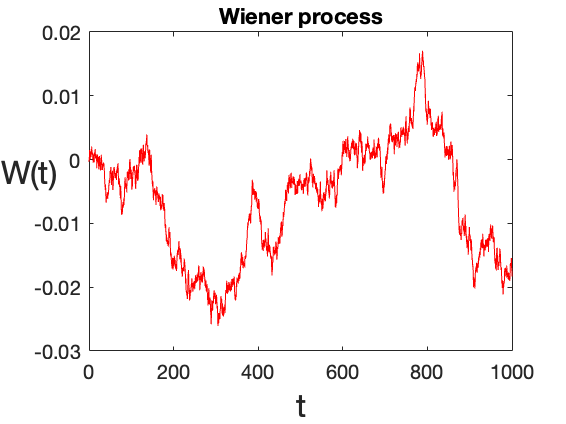

% Y(s) = 1/(1+s*tau)^2 *(U(s)+D(s))
% Find continusous-time stochastic state space model
% Create disturbance as a Wiener process
% Intensity of disturbance Q = 0.001

Qc  = 0.001;
tau = 50;
T = 1000;

% Solution
% Continuous-time system

% Wiener Process 
N = 5000;
dt = T/N;
dW = zeros(1,N);                % preallocate arrays ...
W = zeros(1,N);                 % for efficiency
dW(1) = Qc*sqrt(dt)*randn();    % first approximation outside the loop ...
W(1) = dW(1);                   % since W(0) = 0 is not allowed
for j = 2:N
    dW(j)= Qc*sqrt(dt)*randn(); % general increment
    W(j) = W(j-1) + dW(j);
end
figure;
plot([0:dt:T],[0,W],'r-')       % plot W against t
xlabel('t','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
title("Wiener process");

% mean and variance
MeanWiener = mean(W)

MeanWiener = -0.0065

VarianceWiener = var(W)

VarianceWiener = 8.1507e-05

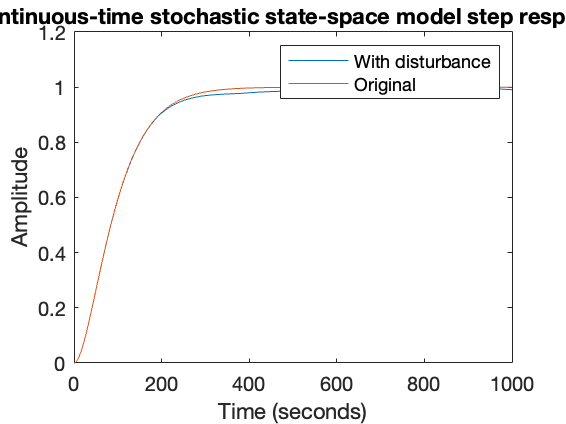



sys = tf(1,[tau^2 2*tau 1]);
step_input = ones(1,N+1);
disturbance = [0,W];
response = lsim(sys,step_input+disturbance,[0:dt:T]);
response_original = lsim(sys,step_input,[0:dt:T]);

figure;
plot([0:dt:T],response);
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Continuous-time stochastic state-space model step response");
hold on
plot([0:dt:T],response_original);
legend("With disturbance","Original");

legend show
fix_ylim = ylim;

## Model derivation

% Discrete-time system ARX
% syms z tau
% b = expand((z+1)*(z+1)*(z+1))
% a = expand((z+1+2*tau*(z-1))*(z+1+2*tau*(z-1))*(z+1+2*tau*(z-1)))

% b = z^3 + 3*z^2 + 3*z + 1
% a = 8*tau^3*z^3 - 24*tau^3*z^2 + 24*tau^3*z - 8*tau^3 + 12*tau^2*z^3 - 12*tau^2*z^2 - 12*tau^2*z + 12*tau^2 + 6*tau*z^3 + 6*tau*z^2 - 6*tau*z - 6*tau + z^3 + 3*z^2 + 3*z + 1

tau1 = 10;
tau = tau1;
b1_ = [1 3 3 1]/(8*tau^3+12*tau^2+6*tau+1);
a1_ = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)]/(8*tau^3+12*tau^2+6*tau+1);
c1_ = 1/(8*tau^3+12*tau^2+6*tau+1);
dsys1 = tf(b1_,a1_,Ts,'Variable','z');

Unrecognized function or variable 'Ts'.

He1 = tf(c1_, a1_, Ts,'Variable','z');  


tau2 = 20;
tau = tau2;
b2_ = [1 3 3 1]/(8*tau^3+12*tau^2+6*tau+1);
a2_ = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)]/(8*tau^3+12*tau^2+6*tau+1);
c2_ = 1/(8*tau^3+12*tau^2+6*tau+1);

dsys2 = tf(b2_,a2_,Ts,'Variable','z');
He2 = tf(c2_, a2_, Ts,'Variable','z'); 

tau3 = 5;
tau = tau3;
b3_ = [1 3 3 1]/(8*tau^3+12*tau^2+6*tau+1);
a3_ = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)]/(8*tau^3+12*tau^2+6*tau+1);
c3_ = 1/(8*tau^3+12*tau^2+6*tau+1);

dsys3 = tf(b3_,a3_,Ts,'Variable','z');
He3 = tf(c3_, a3_, Ts,'Variable','z');  

figure(2);
title("Discrete-time ARX step response");
step(dsys1);

% Noisy discrete-time system
He = tf(c1_, a1_, Ts,'Variable','z');  
step_input = ones(period,1);

response = lsim(dsys1,step_input,T);
noisevec = lsim(He,sqrt(variance)*randn(period,1),T);
y = response+noisevec;

figure(3);
plot(T(1:120),y(1:120));
title("Noisy discrete-time step-response: tau 1");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 2:

% Consider time profile

% Solution
input = ones(3*period,1);       % step signal
time_profile = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);

figure(4);
grid on;
plot(T_all',time_profile);  % time-profile
title("Noisy time-profile of step-responses");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 3:

% Generate input-output data
% Use excitation signals
% Pseudo-binary sequence with 
% low frequency, white noise, high frequency
% Select the signal

% input sequence - low frequency input
p_switch = 0.01;
UU_low = createSignal(p_switch,3*period);
figure(5);
plot(T_all',UU_low);
title("Low frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

% input sequence - white noise input
p_switch = 0.5; 
UU_white = createSignal(p_switch,3*period);
%plot(T_all',UU_white);
title("White noise PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

% input sequence - high frequency input 
p_switch = 0.9; 
UU_high = createSignal(p_switch,3*period);
%plot(T_all',UU_high);
title("High frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)"); 

input = UU_low;      % low-frequency signal
time_profile_low = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
figure(6);
plot(T_all',time_profile_low); 
title("Low frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

input = UU_white;      % white-noise signal
time_profile_white = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
figure(7);
plot(T_all',time_profile_white);
title("White noise input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

input = UU_high;      % high-frequency signal
time_profile_high = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
figure(8);
plot(T_all',time_profile_high); 
title("High frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

% Conclusion
% Because white-noise and high-frequency input signals
% do not show clearly dynamical changes, 
% the low-frequency input signal has been chosen

## Problem 4:

% Perform parameters tracking using different forgetting methods
A0 = [1	-3	2 -2];
B0 = [0.0001	0.0003	0.0003	0.0001];
a = A0;
b = B0;
na = numel(a) - 1;
nb = numel(b);

## Implementing Forgetting Algorithm

% SINGLE STEP
n_samplesBatch = 30;

n_samples = 1000;
input = ones(n_samples,1);
response = lsim(dsys1,input,T');
noisevec = lsim(He1,sqrt(variance)*randn(period,1),T');
output = response+noisevec;
method = 'linear';
theta_step = forgetting(input,output,A0,B0,n_samples,n_samplesBatch,variance,method);



G_truth = dsys1;
G_truth.Name = 'G truth';

G_new = tf(theta_step(na+1:end, end)',[1 theta_step(1:na, end)'],1,'Variable','z');
G_new.Name = 'G estimated';
hold off
figure(9);
hold on
step(G_new);
step(G_truth);
hold off
legend show
fix_ylim = ylim;

figure(10); 
subplot(2,1,1)
AA = theta_step(1:na,:);
plot(1:1:length(input),AA);
ylabel('a(t)')
ttl = 'ARX model parameters: tau1 step response';
title(ttl);

subplot(2,1,2)
BB = theta_step(na+1:end,:);
plot(1:1:length(input),BB); 
ylabel('b(t)')


% TIME_PROFILE_STEP
n_samplesBatch = 30;
n_samples = 3000;
input = ones(3*period,1);
output = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
method = 'linear';
theta_profile = forgetting(input,output,A0,B0,n_samples,n_samplesBatch,variance,method);


G_new1 = tf(theta_profile(na+1:end, 1000)',[1 theta_profile(1:na, 1000)'],1,'Variable','z^-1');
G_new1.Name = 'G estimated tau1';
He_new1 = tf(c1_, G_new1.den{1}, Ts,'Variable','z'); 
G_new2 = tf(theta_profile(na+1:end, 2000)',[1 theta_profile(1:na, 2000)'],1,'Variable','z^-1');
G_new2.Name = 'G estimated tau2';
He_new2 = tf(c2_, G_new2.den{1}, Ts,'Variable','z'); 
G_new3 = tf(theta_profile(na+1:end, 3000)',[1 theta_profile(1:na, 3000)'],1,'Variable','z^-1');
G_new3.Name = 'G estimated tau3';
He_new3 = tf(c3_, G_new3.den{1}, Ts,'Variable','z'); 
hold off
figure(11);
time_profile_est = computeTimeProfile(input,Ts,G_new1,G_new2,G_new3,He_new1,He_new2,He_new3);
plot(T_all',time_profile_est);
hold on
plot(T_all',time_profile);
hold off
legend('estimated','ground truth');
legend show
fix_ylim = ylim;

figure(12); 
subplot(2,1,1)
AA = theta_profile(1:na,:);
plot(1:1:length(input),AA);
hold on
hold off
ylabel('a(t)')
ttl = 'ARX model parameters: time-profile step response';
title(ttl);

subplot(2,1,2)
BB = theta_profile(na+1:end,:);
plot(1:1:length(input),BB);
hold on
hold off 
ylabel('b(t)')


## Time-profile with noisy input low frequency

% TIME_PROFILE_STEP: linear
n_samplesBatch = 30;
n_samples = 3000;
input = UU_low;
output = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
method = 'linear';
theta_noisy = forgetting(input,output,A0,B0,n_samples,n_samplesBatch,variance,method);

G_new1 = tf(theta_noisy(na+1:end, 1000)',[1 theta_noisy(1:na, 1000)'],1,'Variable','z^-1');
G_new1.Name = 'G estimated tau1';
He_new1 = tf(c1_, G_new1.den{1}, Ts,'Variable','z'); 
G_new2 = tf(theta_noisy(na+1:end, 2000)',[1 theta_noisy(1:na, 2000)'],1,'Variable','z^-1');
G_new2.Name = 'G estimated tau2';
He_new2 = tf(c2_, G_new2.den{1}, Ts,'Variable','z'); 
G_new3 = tf(theta_noisy(na+1:end, 3000)',[1 theta_noisy(1:na, 3000)'],1,'Variable','z^-1');
G_new3.Name = 'G estimated tau3';
He_new3 = tf(c3_, G_new3.den{1}, Ts,'Variable','z'); 
hold off
figure(13);
time_profile_est = computeTimeProfile(input,Ts,G_new1,G_new2,G_new3,He_new1,He_new2,He_new3);
plot(T_all',time_profile_est);
hold on
plot(T_all',time_profile_low);
ttl = 'ARX Time-profile linear';
title(ttl);
hold off
legend('estimated','ground truth');
legend show
fix_ylim = ylim;

figure(14); 
subplot(2,1,1)
AA = theta_noisy(1:na,:);
plot(1:1:length(input),AA);
hold on
hold off
ylabel('a(t)')


subplot(2,1,2)
BB = theta_noisy(na+1:end,:);
plot(1:1:length(input),BB);
hold on
hold off 
ylabel('b(t)')

MSE = calculateMSE(time_profile_est,output);
disp('Mean Square Error');
disp(MSE);

% TIME_PROFILE_STEP: exponential
n_samplesBatch = 30;
n_samples = 3000;
input = UU_low;
output = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
method = 'exponential';
theta_noisy = forgetting(input,output,A0,B0,n_samples,n_samplesBatch,variance,method);

G_new1 = tf(theta_noisy(na+1:end, 1000)',[1 theta_noisy(1:na, 1000)'],1,'Variable','z^-1');
G_new1.Name = 'G estimated tau1';
He_new1 = tf(c1_, G_new1.den{1}, Ts,'Variable','z'); 
G_new2 = tf(theta_noisy(na+1:end, 2000)',[1 theta_noisy(1:na, 2000)'],1,'Variable','z^-1');
G_new2.Name = 'G estimated tau2';
He_new2 = tf(c2_, G_new2.den{1}, Ts,'Variable','z'); 
G_new3 = tf(theta_noisy(na+1:end, 3000)',[1 theta_noisy(1:na, 3000)'],1,'Variable','z^-1');
G_new3.Name = 'G estimated tau3';
He_new3 = tf(c3_, G_new3.den{1}, Ts,'Variable','z'); 
hold off
figure(15);
time_profile_est = computeTimeProfile(input,Ts,G_new1,G_new2,G_new3,He_new1,He_new2,He_new3);
plot(T_all',time_profile_est);
hold on
plot(T_all',time_profile_low);
ttl = 'ARX Time-profile exponential';
title(ttl);
hold off
legend('estimated','ground truth');
legend show
fix_ylim = ylim;

figure(16); 
subplot(2,1,1)
AA = theta_noisy(1:na,:);
plot(1:1:length(input),AA);
hold on
hold off
ylabel('a(t)')


subplot(2,1,2)
BB = theta_noisy(na+1:end,:);
plot(1:1:length(input),BB);
hold on
hold off 
ylabel('b(t)')

MSE = calculateMSE(time_profile_est,output);
disp('Mean Square Error');
disp(MSE);

% TIME_PROFILE_STEP: restricted_linear
n_samplesBatch = 30;
n_samples = 3000;
input = UU_low;
output = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
method = 'restricted_linear';
theta_noisy = forgetting(input,output,A0,B0,n_samples,n_samplesBatch,variance,method);

G_new1 = tf(theta_noisy(na+1:end, 1000)',[1 theta_noisy(1:na, 1000)'],1,'Variable','z^-1');
G_new1.Name = 'G estimated tau1';
He_new1 = tf(c1_, G_new1.den{1}, Ts,'Variable','z'); 
G_new2 = tf(theta_noisy(na+1:end, 2000)',[1 theta_noisy(1:na, 2000)'],1,'Variable','z^-1');
G_new2.Name = 'G estimated tau2';
He_new2 = tf(c2_, G_new2.den{1}, Ts,'Variable','z'); 
G_new3 = tf(theta_noisy(na+1:end, 3000)',[1 theta_noisy(1:na, 3000)'],1,'Variable','z^-1');
G_new3.Name = 'G estimated tau3';
He_new3 = tf(c3_, G_new3.den{1}, Ts,'Variable','z'); 
hold off
figure(17);
time_profile_est = computeTimeProfile(input,Ts,G_new1,G_new2,G_new3,He_new1,He_new2,He_new3);
plot(T_all',time_profile_est);
hold on
plot(T_all',time_profile_low);
ttl = 'ARX Time-profile restricted linear';
title(ttl);
hold off
legend('estimated','ground truth');
legend show
fix_ylim = ylim;

figure(18); 
subplot(2,1,1)
AA = theta_noisy(1:na,:);
plot(1:1:length(input),AA);
hold on
hold off
ylabel('a(t)')


subplot(2,1,2)
BB = theta_noisy(na+1:end,:);
plot(1:1:length(input),BB);
hold on
hold off 
ylabel('b(t)')

MSE = calculateMSE(time_profile_est,output);
disp('Mean Square Error');
disp(MSE);

% TIME_PROFILE_STEP: restricted_exponential
n_samplesBatch = 30;
n_samples = 3000;
input = UU_low;
output = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
method = 'restricted_exponential';
theta_noisy = forgetting(input,output,A0,B0,n_samples,n_samplesBatch,variance,method);

G_new1 = tf(theta_noisy(na+1:end, 1000)',[1 theta_noisy(1:na, 1000)'],1,'Variable','z^-1');
G_new1.Name = 'G estimated tau1';
He_new1 = tf(c1_, G_new1.den{1}, Ts,'Variable','z'); 
G_new2 = tf(theta_noisy(na+1:end, 2000)',[1 theta_noisy(1:na, 2000)'],1,'Variable','z^-1');
G_new2.Name = 'G estimated tau2';
He_new2 = tf(c2_, G_new2.den{1}, Ts,'Variable','z'); 
G_new3 = tf(theta_noisy(na+1:end, 3000)',[1 theta_noisy(1:na, 3000)'],1,'Variable','z^-1');
G_new3.Name = 'G estimated tau3';
He_new3 = tf(c3_, G_new3.den{1}, Ts,'Variable','z'); 
hold off
figure(19);
time_profile_est = computeTimeProfile(input,Ts,G_new1,G_new2,G_new3,He_new1,He_new2,He_new3);
plot(T_all',time_profile_est);
hold on
plot(T_all',time_profile_low);
ttl = 'ARX Time-profile restricted exponential';
title(ttl);
hold off
legend('estimated','ground truth');
legend show
fix_ylim = ylim;

figure(20); 
subplot(2,1,1)
AA = theta_noisy(1:na,:);
plot(1:1:length(input),AA);
hold on
hold off
ylabel('a(t)')


subplot(2,1,2)
BB = theta_noisy(na+1:end,:);
plot(1:1:length(input),BB);
hold on
hold off 
ylabel('b(t)')

MSE = calculateMSE(time_profile_est,output);
disp('Mean Square Error');
disp(MSE);

% TIME_PROFILE_STEP: no
n_samplesBatch = 30;
n_samples = 3000;
input = UU_low;
output = computeTimeProfile(input,Ts,dsys1,dsys2,dsys3,He1,He2,He3);
method = 'no';
theta_noisy = forgetting(input,output,A0,B0,n_samples,n_samplesBatch,variance,method);

G_new1 = tf(theta_noisy(na+1:end, 1000)',[1 theta_noisy(1:na, 1000)'],1,'Variable','z^-1');
G_new1.Name = 'G estimated tau1';
He_new1 = tf(c1_, G_new1.den{1}, Ts,'Variable','z'); 
G_new2 = tf(theta_noisy(na+1:end, 2000)',[1 theta_noisy(1:na, 2000)'],1,'Variable','z^-1');
G_new2.Name = 'G estimated tau2';
He_new2 = tf(c2_, G_new2.den{1}, Ts,'Variable','z'); 
G_new3 = tf(theta_noisy(na+1:end, 3000)',[1 theta_noisy(1:na, 3000)'],1,'Variable','z^-1');
G_new3.Name = 'G estimated tau3';
He_new3 = tf(c3_, G_new3.den{1}, Ts,'Variable','z'); 
hold off
figure(21);
time_profile_est = computeTimeProfile(input,Ts,G_new1,G_new2,G_new3,He_new1,He_new2,He_new3);
plot(T_all',time_profile_est);
hold on
plot(T_all',time_profile_low);
ttl = 'ARX Time-profile no';
title(ttl);
hold off
legend('estimated','ground truth');
legend show
fix_ylim = ylim;

figure(22); 
subplot(2,1,1)
AA = theta_noisy(1:na,:);
plot(1:1:length(input),AA);
hold on
hold off
ylabel('a(t)')


subplot(2,1,2)
BB = theta_noisy(na+1:end,:);
plot(1:1:length(input),BB);
hold on
hold off 
ylabel('b(t)')

MSE = calculateMSE(time_profile_est,output);
disp('Mean Square Error');
disp(MSE);

## Problem 5

% Conclusion
% Lessons learned

% The result of estimation depends on initial setup of co-variance

% Minimal error is usually achieved by exponential forgetting methods:
% either restricted or not

## Additional tools

% Storing figures
if storeFigures
    for i=1:14
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end